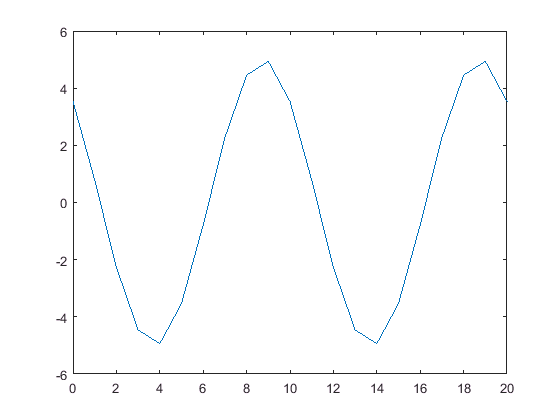

%Input er et analogt signal. MATLAB kan ikke håndtere analoge signaler
%Derfor samples signalet, hvor tiden bliver til n * Ts (samplingnummer gange periodetid for samples)
f1=1000; %Signalfrekvens
fs=10000; %Sampelfrekvens
Ts=1/fs; %Periodetid for samples
N=1000; %Antal samples
n=0:N-1; %n betyder, at summen udregnes fra 0 til N-1

A1=5; %Amplituden
fase1=pi/4; %Faseforskydning

x=A1*cos(2*pi*f1*n*Ts+fase1); %Signal omskrevet fra analog til diskret

plot(n,x) %Plotter kontinuer graf
axis([0 20 -A1-1 A1+1]) %Zoomer ind

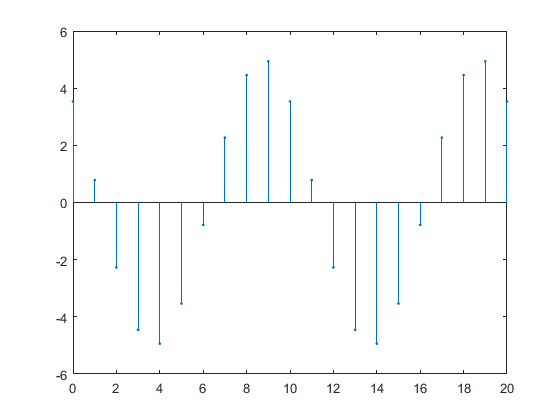

stem(n,x,'.') %Plotter diskret graf
axis([0 20 -A1-1 A1+1]) %Zoomer ind

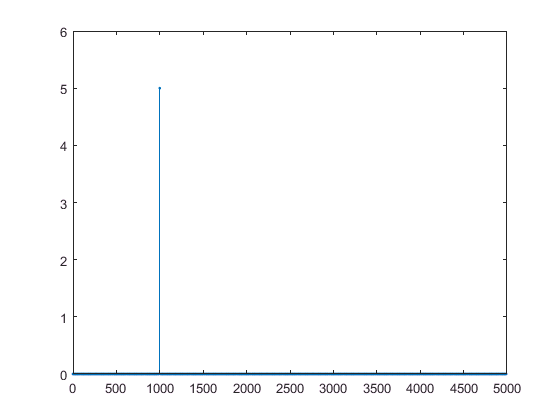


X=(2/N)*fft(x, N); %(2/N) skal ikke forstås. fft tager signalet og antallet af samples
%Resultatet er en Fourier-transformation af signalet

k=1:N/2; %Hvis vi kun ønsker at se den første halvdel af transformationen
f=(k-1)*fs/N; %Frekvensvektor med beregningspunkterne for X(f)

stem(f,abs(X(k)), '.') %Amplitudespektrum plottes

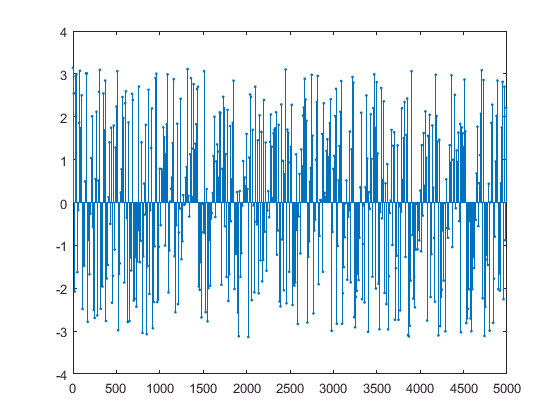

%Kommentar til plot:
%Amplituden er korrekt = 5
%Den er plottet lodret ved frekvensen f1 = 1000

stem(f,angle(X(k)),'.') %Frekvensspektrum plottes

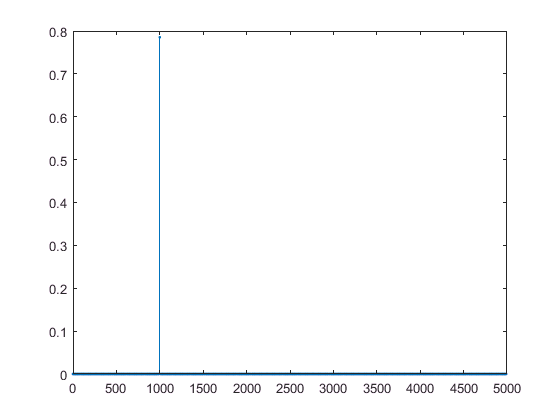

%Kommentar til plot:
%Den viser fasen for alle frekvenserne
%Grunden til, at der er så mange faser, er, at der er utrolig meget støj
%Støjen har meget lille amplitude og vises derfor ikke

nuller=find(0.001>abs(X)); %De ubetydende værdier af X nulstilles
X(nuller)=0; %Ekstremt små amplituder fjernes fra fasespektret
stem(f,angle(X(k)), '.') %X plottes igen

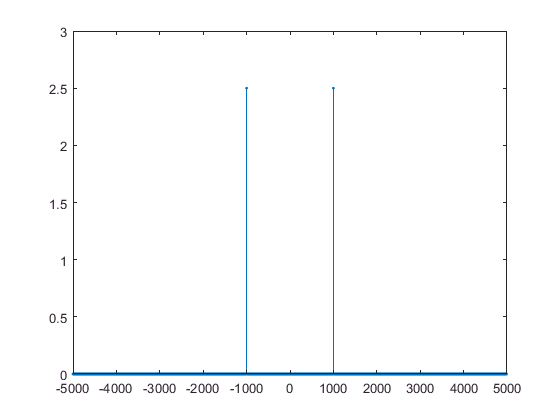

%Kommentar til plot:
%Vinklen er her cirka 0,8

%Hidtil er kun enkeltsidet spektrum fundet
%Nu vil vi også finde et dobbeltsidet spektrum
Xdob=0.5*fftshift(X); %Amplitude halveres
k=(-N/2):(N/2-1); %Indeksering indeholder både negativ og positiv
f=k*fs/N;
stem(f,abs(Xdob),'.')

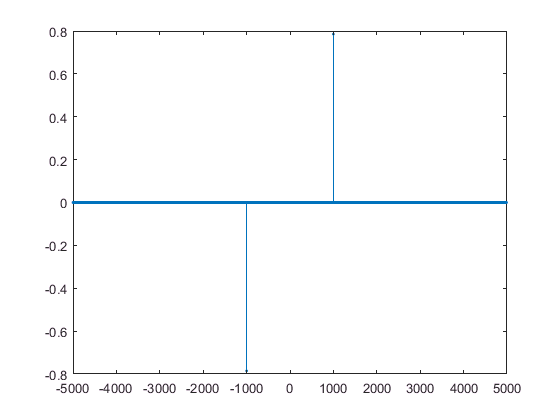

stem(f,angle(Xdob),'.')

%Kommentar:
%Plottene er komplekse (dobbeltsidet) som forventet.